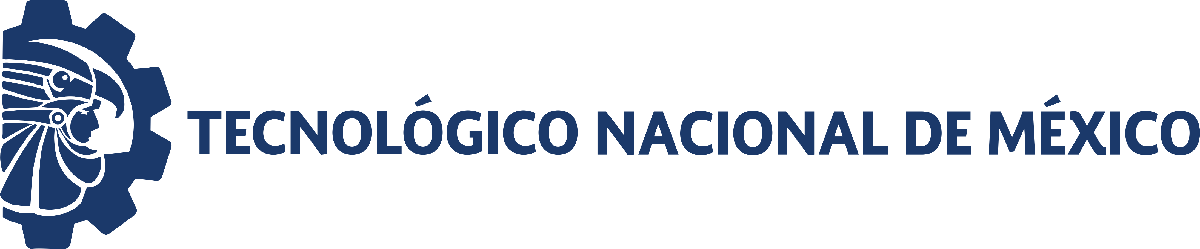                                 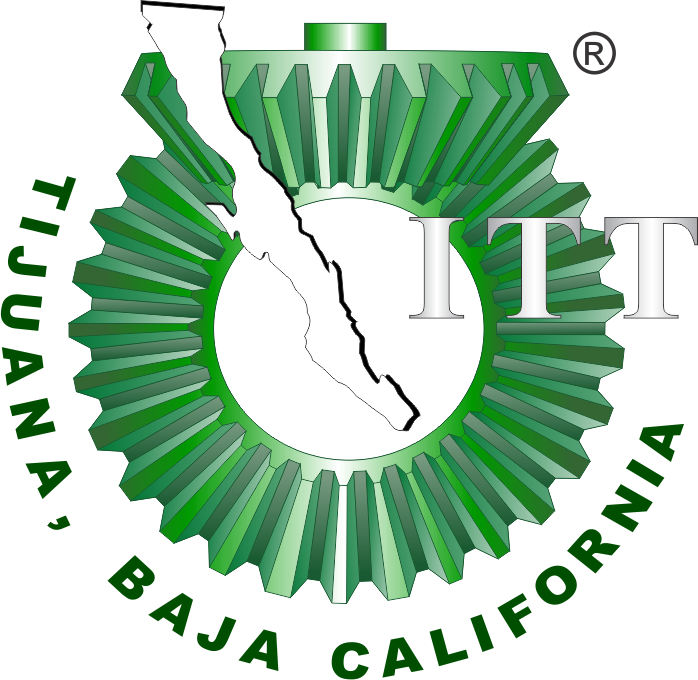

# Práctica 2: Sistema presa-depredador de Lotka-Volterra

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

**Objetivo. **Solucionar las ecuaciones de Lotka-Volterra para estudiar e ilustrar su dinamica en seriesde tiempo y el plano de fase. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot{x} =\alpha x-\beta \textrm{xy},$$



$$\dot{y} =\delta \textrm{xy}-\gamma y,$$


con los valores de los parametros $\alpha =0\ldotp 5,\;\beta =0\ldotp 01,\;\delta =0\ldotp 005$ y $\gamma =0\ldotp 2,$ y las condiciones iniciales $x\left(0\right)=x_0 =75$ y $y\left(0\right)=y_0 =75$.

[Figura representativa del sistema elaborada e BioRender]

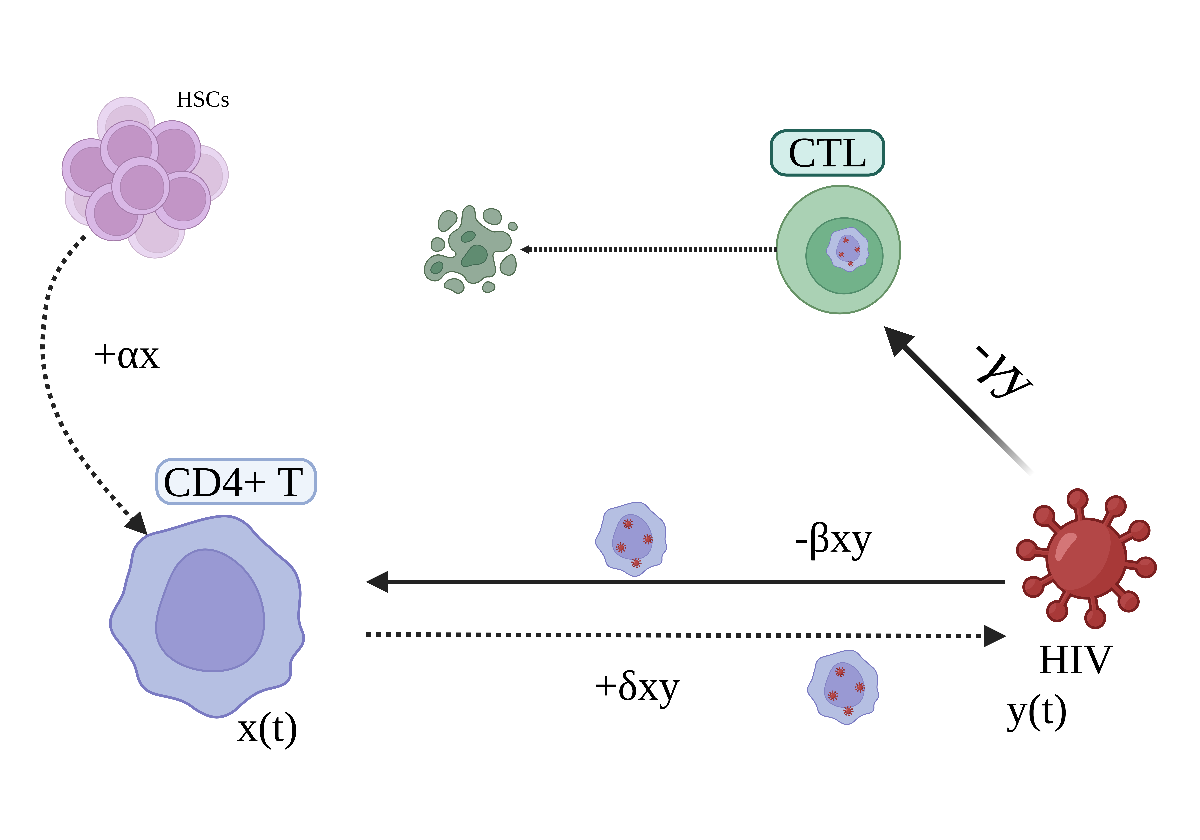

FIgure. HIV ($y\left(t\right)$) encounter CD4+ T cells ($x\left(t\right)$), these encounters result in both the decrease [negative feedback] of T cells at a rate $\beta$, and the expansion [positive feedback] of the Virion at a rate $\delta$. Addittionally, the virion is eliminated by CTLs [exponential decay] at a rate given by $\gamma$, and CD4+ T cells are derived [exponential growth] at a rate denoted by $\alpha$.

## Información general

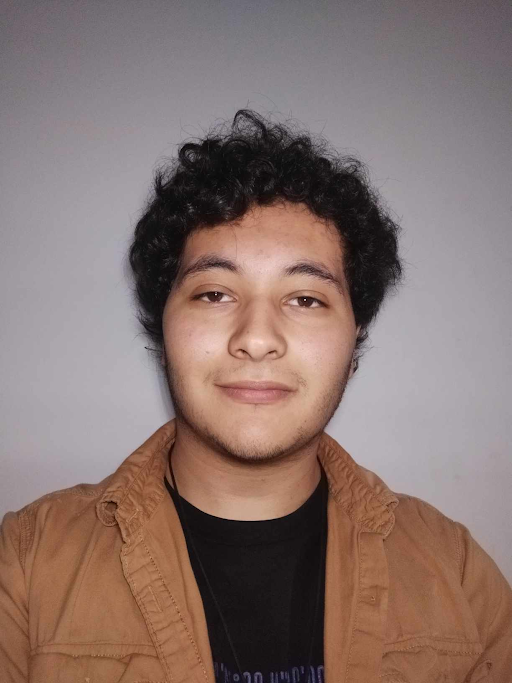

Nombre del alumno: **Hector Andres Fernandez Esquivel**

Número de control: **21212153**

Correo institucional: **l21212153@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
c1 = [98,227,218]/255;
c2 = [132,79,232]/255;
c3 = [98,227,174]/255;


## Parameters and initial conditions

alpha=0.5;      beta = 0.01;
delta = 0.001;  gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;

## Solution by Euler's method

% dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = 1E-4;
for i=1:numel(dt)
    [t,x,y] = sys_Euler(x0,y0,dt(i),tend,P);
    plotEDOS(t,x,y,P,dt(i));
    exportgraphics(gcf,['Lotka-Volterra Euler ', num2str(dt(i)), '.pdf'], 'ContentType', 'Vector')
end

## Solution by Heun's method

% dt = [2,1,0.5,0.25,1E-1,1E-2,1E-3,1E-4,1E-5,1E-6];
dt = 1E-1;
for i=1:numel(dt)
    [t,x,y] = sys_Heun(x0,y0,dt(i),tend,P);
    plotEDOS(t,x,y,P,dt(i))
exportgraphics(gcf,['Lotka-Volterra Heun ', num2str(dt(i)), '.pdf'], 'ContentType', 'Vector')
end

## Simulink

file = 'Fernandez212121';
sim(file);
parameters.StopTime = '100';

### Solution by ode15s [Stiff solver]

parameters.Solver = 'ode15s';
s15s = sim(file,parameters);
plotEDOS(s15s.t,s15s.x,s15s.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode15s.pdf'], 'ContentType', 'Vector')

### Solution by ode23t [Stiff solver]

parameters.Solver = 'ode23t';
s23t = sim(file,parameters);
plotEDOS(s23t.t,s23t.x,s23t.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23t.pdf'], 'ContentType', 'Vector')

### Solution by ode23tb [Stiff solver]

parameters.Solver = 'ode23tb';
s23tb = sim(file,parameters);
plotEDOS(s23tb.t,s23tb.x,s23tb.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode23tb.pdf'], 'ContentType', 'Vector')

### Solution by ode45 [Nonstiff solver]

parameters.Solver = 'ode45';
s45 = sim(file,parameters);
plotEDOS(s45.t,s45.x,s45.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode45.pdf'], 'ContentType', 'Vector')

### Solution by ode113 [Nonstiff solver]

parameters.Solver = 'ode113';
s113 = sim(file,parameters);
plotEDOS(s113.t,s113.x,s113.y,P,0)
exportgraphics(gcf,['Lotka-Volterra ode113.pdf'], 'ContentType', 'Vector')

Con base en las simulaciones numericas y presentado el comportamiento grafico en los distintos solucionadores donde se consideran condiciones iguales, se pueden observar cercanias en cualquier solucionador, aunque el caso donde las oscilaciones de la solucion son observables dentro del solucionador Ode45, el caso con oscilaciones minimas observables es el solucionador Ode113, donde la solucion presenta el menor numero de pasos requeridos para determinar la cercania al valor por lo tanto, se concluye que el sistema de Lotka-Volterra es nonstiff.

Referencia.

Aliyu, B. K., Osheku, C. A., Funmilayo, A. A., & Musa, J. I. (2014). Identifying stiff ordinary differential equations and problem solving environments (PSEs). *Journal of Scientific Research & Reports*, *3*(11), 1420-1448.

## Equilibrium points and Jacobian matrix

clear; close all; clc
syms x y alpha beta delta gamma
dx = alpha*x - beta*x*y;
dy = delta*x*y - gamma*y;
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ',num2str(length(edos.x)),' equilibrium points.'])
X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
syms x0 y0 x1 y1
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1])
clear alpha beta delta gamma
alpha = 0.5; beta = 0.01; 
delta = 0.001; gamma = 0.2;
disp('(x0,y0) = (0,0)'); disp(['(x1,y1) = (',num2str(gamma/delta),',',num2str(alpha/beta),')'])

## Local stability    

clc; clear;
alpha = 0.5; beta = 0.01; 
delta = 0.001; gamma = 0.2;
syms x y
dx = alpha*x - beta*x*y == 0;
dy = delta*x*y - gamma*y == 0;
edos = solve([dx,dy],[x,y]); 
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
clear x y
x = [x0; x1]; y = [y0; y1];
var = {'(x0,y0)'; '(x1,y1)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)
L = zeros(length(x),length(x));
for i = 1:length(x)
    J = [alpha - beta*y(i),         -beta*x(i);
                delta*y(i), delta*x(i) - gamma]
    L(i,:) = eig(J);
end
L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eignen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)


$$\lambda_1 <0<\lambda_2 \;\left(x_0 ,y_0 \right)$$


Similar al caso nodo, en este los valores son reales y se consideran estables al ser propios negativos e inestables al ser propios positivos, en este caso siendo con signos opuestos, este sistema se describe como inestable.


$$\textrm{Re}\lambda_{1,2} =0\;\left(x_1 ,y_1 \right)$$


### Equilibrium points

alpha=0.5;      beta = 0.01;
delta = 0.001;  gamma = 0.2;
P = [alpha,beta,delta,gamma];
x0 = 75; y0 = 75; tend = 100;
dt = 1E-4;
[t,x,y] = sys_Heun(x0,y0,dt,tend,P);
plotEDOS(t,x,y,P,dt); ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Lotka-Volterra Equilibria.pdf','ContentType','Vector')

### Data fitting

clc; clear; close all

### Raw data

sys = readmatrix('data.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
alpha=0.5;      beta = 0.01;
delta = 0.001;  gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOSfit(to,xo,yo,P,0); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra.pdf','ContentType','Vector')

### Smooth data

xo = smoothdata(xo,'gaussian',5);
yo = smoothdata(yo,'gaussian',5);
plotEDOSfit(to,xo,yo,P,0); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra (smooth).pdf','ContentType','Vector')

### Fit data

P0 = [1;0.01;0.01;0.1;];
mdl = variant(to,xo,yo,P0);
fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResults(to,[xo,xa],[yo,ya],P); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra (fitted).pdf','ContentType','Vector')

### Experimental data ???

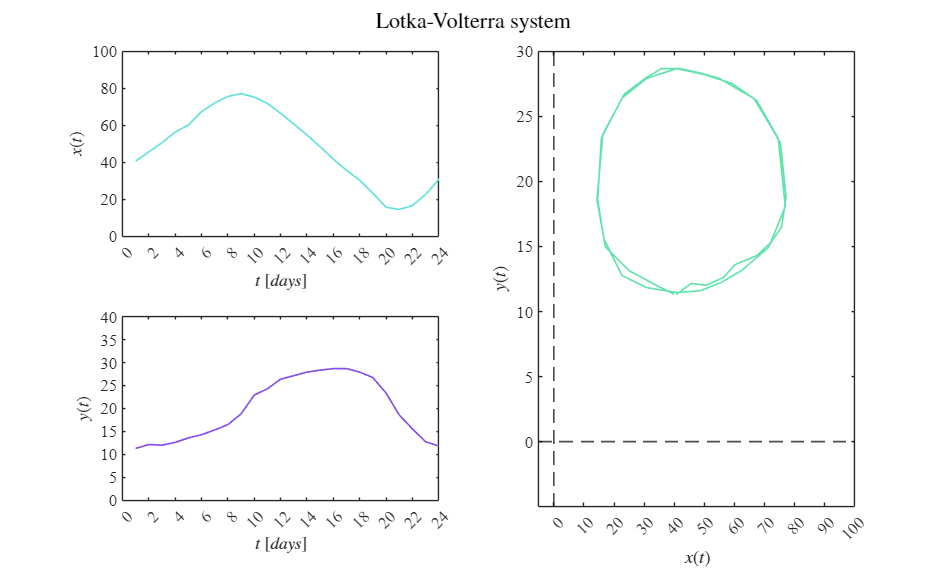

clc; clear; close all
sys = readmatrix('DATA_EX.csv');
to = sys(:,1); xo = sys(:,2); yo = sys(:,3);
alpha=0.5;      beta = 0.01;
delta = 0.001;  gamma = 0.2;
P = [alpha,beta,delta,gamma];
plotEDOSfitex(to,xo,yo,P,0); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra example.pdf','ContentType','Vector')

### Smooth data

xo = smoothdata(xo,'lowess',3);
yo = smoothdata(yo,'lowess',3);
plotEDOSfitex(to,xo,yo,P,0); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra (smooth).pdf','ContentType','Vector')

### Fit data

P0 = [1.6;0.0153;0.013;0.2;];
mdl = variant(to,xo,yo,P0);

t-Studen value: 1.9893
 

Sample size (n): 43
Parameters to be estimated (pars): 4
Degrees of freedom: 82
Significance level (alpha): 0.05
-Student value: 1.9893
Adjusted R-squared: 0.8377
Corrected AIC (n/pars<40) : 610.2598
    Parameters    Estimate        SE           MoE                CI95               Pvalue  
    __________    ________    __________    _________    ______________________    __________

      alpha        0.23038      0.026608     0.052932      0.17745      0.28332    3.4422e-13
      beta        0.012446     0.0018432    0.0036667    0.0087798     0.016113    1.9275e-09
      delta       0.006932    0.00090602    0.0018024    0.0051296    0.0087343     3.418e-11
      gamma        0.34675      0.047065     0.093627      0.25312      0.44037    1.2326e-10



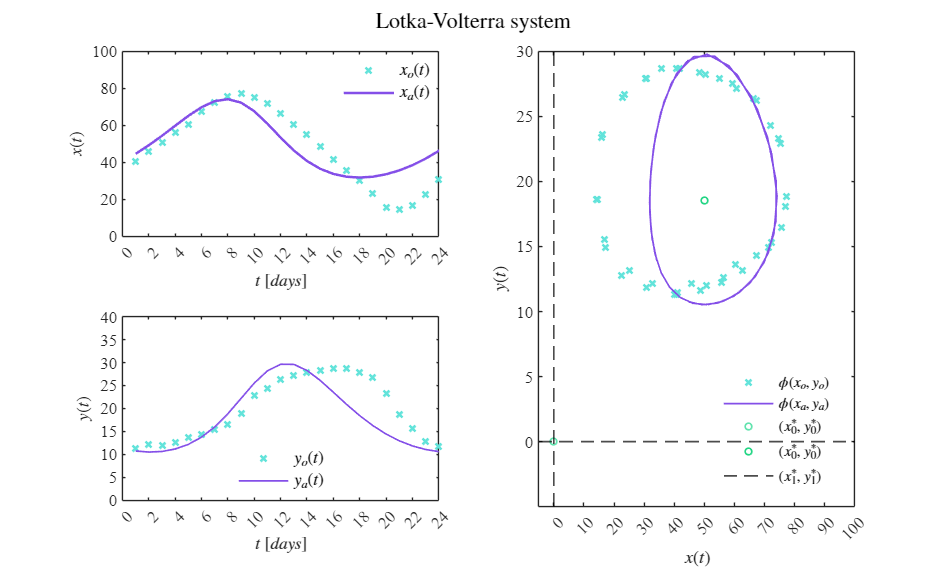

fa = mdl.Fitted;
fx = reshape(fa,[],2);
xa = fx(:,1); ya = fx(:,2);
P = table2array(mdl.Coefficients(:,1));
plotResultsex(to,[xo,xa],[yo,ya],P); 
ttl = 'Lotka-Volterra system'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'Data fitting Lotka-Volterra (fitted).pdf','ContentType','Vector')

## Functions

### Euler's method

function [t,x,y] = sys_Euler(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n
        x(i+1) = x(i) + (alpha*x(i) - beta*x(i)*y(i))*dt;
        y(i+1) = y(i) + (delta*x(i)*y(i) - gamma*y(i))*dt;
    end
end

### Heun's method

function [t,x,y] = sys_Heun(x0,y0,dt,tend,P)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    n = round(tend/dt);
    t = (0:dt:tend)';
    x = zeros(length(t),1); x(1) = x0;
    y = zeros(length(t),1); y(1) = y0;

    for i = 1:n    
        [fx,fy] = f(x(i),y(i));  
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;

        [fxn, fyn] = f(xn,yn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;  
    end

  function [dx, dy] = f(x,y)
    dx = alpha*x - beta*x*y;
    dy = delta*x*y - gamma*y;
  end

end

### Solutions and trajectories

function plotEDOS(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 600]); yticks(0:100:600)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    plot(x(1),y(1),'o','MarkerSize',5,'Color',([42 214 13]/255))
    plot(0,0,'x','MarkerSize',5,'LineWidth',1.5,'Color',[15 102 201]/255)
    plot(gamma/delta,alpha/beta,'x','MarkerSize',5,'LineWidth',1,'Color',[35 213 132]/255)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-60 600]); xticks(0:100:600)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend ('$\phi(x,y)$','$(x(0),y(0))$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','none','Position', ...
        [0.7644,0.25,0.13,0.015],'Box','Off')

    if dt == 0
    ttl = ['Lotka-Volterra system'];
    sgtitle(ttl,'Interpreter','latex')  
    else
    ttl = ['Step size: ',num2str(dt)];
    sgtitle(ttl,'Interpreter','latex')
    end
end

function plotEDOSfit(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    if dt == 0
    ttl = ['Lotka-Volterra system'];
    sgtitle(ttl,'Interpreter','latex')  
    else
    ttl = ['Step size: ',num2str(dt)];
    sgtitle(ttl,'Interpreter','latex')
    end
end

function plotResults(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1.5,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    L = legend ('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c2)
    plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',c3)
    plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',[35 213 132]/255)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 100]); yticks(0:10:100)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    end

    function plotEDOSfitex(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 40]); yticks(0:5:40)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x,y,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 30]); yticks(0:5:30)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')

    if dt == 0
    ttl = ['Lotka-Volterra system'];
    sgtitle(ttl,'Interpreter','latex')  
    else
    ttl = ['Step size: ',num2str(dt)];
    sgtitle(ttl,'Interpreter','latex')
    end
    end

    function plotResultsex(t,x,y,P,dt)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(2,2,1)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1.5,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 100]); yticks(0:20:100)

    subplot(2,2,3)
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    L = legend ('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    xlim([0 24]); xticks(0:2:24)
    ylim([0 40]); yticks(0:5:40)

    subplot(2,2,[2 4])
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(x(:,1),y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(x(:,2),y(:,2),'-','LineWidth',1,'Color',c2)
    plot(0,0,'o','MarkerSize',4,'LineWidth',1,'Color',c3)
    plot(gamma/delta,alpha/beta,'o','MarkerSize',4,'LineWidth',1,'Color',[35 213 132]/255)
    xlabel('$x(t)$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([-5 100]); xticks(0:10:100)
    ylim([-5 30]); yticks(0:5:30)
    xline(0,'--','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    L = legend ('$\phi(x_o,y_o)$','$\phi(x_a,y_a)$','$(x^*_0,y^*_0)$','$(x^*_0,y^*_0)$','$(x^*_1,y^*_1)$');
    set(L,'Interpreter','latex','Location','Best','Box','Off')
    end

### Nonlinear regression algorithm

function mdl= variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        alpha = p(1); beta = p(2); delta = p(3); gamma = p(4);
        dt = 1E-2;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = alpha*x-beta*x*y;
            dy = delta*x*y-gamma*y;
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha=0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['alpha';'beta ';'delta';'gamma'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['t-Studen value: ',num2str(tval)])
    disp(' ')
    
    fprintf('\nSample size (n): %d', numel(xo))
    fprintf('\nParameters to be estimated (pars): %d', numel(P0))
    fprintf('\nDegrees of freedom: %d', dof)
    fprintf('\nSignificance level (alpha): %.2f', alpha)
    fprintf('\n-Student value: %.4f', tval)
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted)
    fprintf('\nCorrected AIC (n/pars<40) : %.4f\n', mdl.ModelCriterion.AICc)
    
    disp(Results)
end 
